# The finite element method

***Note: ****For simplicity we only consider a 2D problem in divergence form and forgo the strict use of Sobolev space theory, needed for the rigerous treatment of the FEM. A comprehensive mathematical  formulation can instead found in the accompanying paper, for example.*

Let $\Omega \in \mathbf{R}^2$ be a domain with $\partial \Omega = \Gamma_1 \cup \Gamma_2, \ \Gamma_1^{\circ} \cap \Gamma_2^{\circ} = \emptyset$. Further let $f :\Omega \to \mathbf{R}$, $g:\Gamma_1 \to \mathbf{R}$, $h:\Gamma_2 \to \mathbf{R}$ be continous  and let $a:\Omega \to \mathbf{R}$ be continous, bounded and differentiable mappings. We seek to find a twice continously differentiable mapping $u: \bar{\Omega} \to \mathbf{R}$, which solves the strong form of the following partial differential equation (PDE).


$$
div \left ( a \, grad\, u \right ) = \nabla \cdot \left ( a \nabla u \right )  = -f, \text{in} \ \Omega, \\
u_{\vert \Gamma_1} = g, \text{ on } \Gamma_1, \\
\frac{\partial u}{\partial n}{\vert_{\Gamma_2} = h, \text{ on } \Gamma_2. 

$$


Here, Dirichlet bundary conditions (the first type) and Neumann boundary conditions (the second type) are considered.

Instead of solving the strong form of the PDE, we seek to solve the so called weak form of the PDE which is obtained by multiplying above equation with so called test functions $\varphi$ and integarting it over the whole domain.  In other words, find $u
$, such that for all test functions $\varphi$


$$\int \limits_{\Omega} \nabla \cdot \left ( a \nabla u \right ) \varphi \ \mathrm{dA} = - \int \limits_{\Omega} f \varphi \ \mathrm{dA}.$$


By exploting $\nabla \cdot \left ( u v\right) = \nabla u \cdot v + u \nabla \cdot v$ and Gauss' divergence theorem we have


$$\int \limits_{\Omega} a \nabla u \cdot \nabla \varphi \ \mathrm{dA} = \int\limits_{\partial \Omega} \varphi a \nabla u \cdot \vec{n} \ \mathrm{ds} + \int \limits_{\Omega} f \varphi \ \mathrm{dA}.$$


Where $\vec{n}$ denotes the puter normal to $\Omega$. Taking into accout only those testfunctions $\varphi$ that are $0$ on $\Gamma_1$ and inserting the indentity given by the Neumann boundary condtions, we end up with


$$\int \limits_{\Omega} a \nabla u \cdot \nabla \varphi \ \mathrm{dA} = \int\limits_{\Gamma_2} a \varphi  h \ \mathrm{ds} + \int \limits_{\Omega} f \varphi \ \mathrm{dA}, \text{ for all }\varphi,\text{ with }\varphi=0 \text{ on }\Gamma_1,$$


or, by using the standard $L^2$ inner product notation:


$$\langle \nabla u, \nabla \varphi \rangle_{\Omega} = \langle f, \varphi \rangle_{\Omega} + \langle h, \varphi \rangle_{\Gamma_2}.$$


Discretization is perfomed with the Galerkin approach. There, the same  finite dimensional vector space $V$ is chosen as ansatz space for the test and trail functions. Thus, the problem tansforms to:

*Find  *$u_h \in V$*with *$u_{h \vert_{\Gamma1}} =g$* on *$\Gamma_1$*, which solves *


$$\langle \nabla u_h, \nabla \varphi \rangle_{\Omega} = \langle f, \varphi \rangle_{\Omega} + \langle h, \varphi \rangle_{\Gamma_2}$$
 

*for all *$v \in V.$

Representing all participating functions in terms of a basis set $\lbrace \varphi_k \rbrace_{k=1, \ldots, n}$, i.e., $u_h = \sum \limits_{k=1}^n \alpha_k \varphi_k$, the following can be obtained:


$$\langle \sum \limits_{k=1}^n \alpha_k \nabla \varphi_k, \nabla \varphi_l \rangle_{\Omega} = \langle f, \varphi_l \rangle_{\Omega} + \langle h, \varphi_l \rangle_{\Gamma_2}, \text{ for }l=1,\ldots,n \\
\Leftrightarrow \sum \limits_{k=1}^n \alpha_k \langle \nabla \varphi_k, \nabla \varphi_l \rangle_{\Omega} = \langle f, \varphi_l \rangle_{\Omega} + \langle h, \varphi_l \rangle_{\Gamma_2}, \text{ for }l=1,\ldots,n,$$


where teh coefficients $\alpha_k$ are the only unknowns. Therefore the above can be written as a system of linear equations of the form


$$C a = b_{\text{force}} + b_{\text{boundary}},$$


whith 


$$C = \pmatrix{\langle \nabla \varphi_1, \nabla \varphi_1 \rangle_{\Omega} & \ldots & \langle \nabla \varphi_1, \nabla \varphi_n \rangle_{\Omega} \cr \vdots & \vdots &\vdots \cr \langle \nabla \varphi_n, \nabla \varphi_1 \rangle_{\Omega} & \ldots & \langle \nabla \varphi_n, \nabla \varphi_n \rangle_{\Omega}}, a= \pmatrix{\alpha_1 \cr \vdots \cr \alpha_n}, b_{\text{force}} = \pmatrix{\langle f, \varphi_1 \rangle_{\Omega} \cr \vdots \cr \langle f, \varphi_n \rangle_{\Omega} }, \text{ and } b_{\text{boundary}} = \pmatrix{\langle h, \varphi_1 \rangle_{\Gamma_2} \cr \vdots \cr \langle h, \varphi_n \rangle_{\Gamma_2}}.$$


# Space and geometry discretization

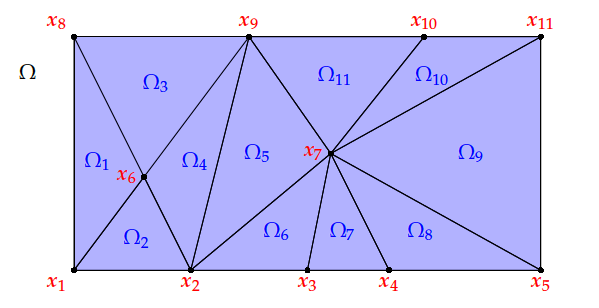

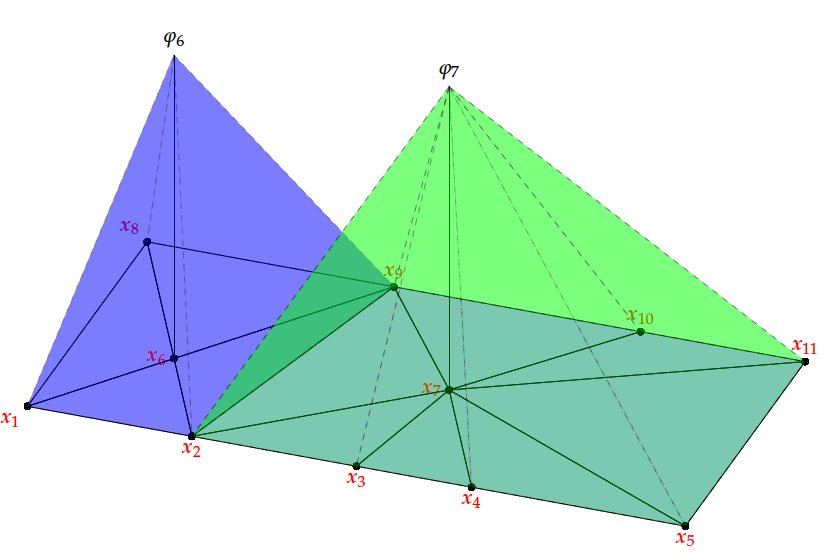

% Gebiet Omega=[0,1]x[0,1], Dirichlet-Rand ist der ganze Rand und rechte
% Seite ist 0.

%% mesh erzeugen, d.h. Koordinatenmatrix und Elementmatrix
co = [ 0  , 0  ; ...
       1/3, 0  ; ...
       2/3, 0  ; ...
       1  , 0  ; ...
       0  , 1/3; ...
       1/3, 1/3; ...
       2/3, 1/3; ...
       1  , 1/3; ... 
       0  , 2/3; ...
       1/3, 2/3; ...
       2/3, 2/3; ...
       1  , 2/3; ...
       0  , 1  ; ...
       1/3, 1  ; ...
       2/3, 1  ; ...
       1  , 1  ];

elem = [ 1 ,2 , 5; ...
         2 ,6 , 5; ...
         5 ,6 , 9; ...
         6 ,10, 9; ...
         9 ,10,13; ...
         10,14,13; ...
         2 ,3 , 6; ...
         3 ,7 , 6; ...
         6 ,7 ,10; ...
         7 ,11,10; ...
         10,11,14; ...
         11,15,14; ...
         3 ,4 , 7; ...
         4 ,8 , 7; ...
         7 ,8 ,11; ...
         8 ,12,11; ...
         11,12,15; ...
         12,16,15];

%% Steiffigkeitsmatrix assemblieren
n=size(co,1);
m=size(elem,1);

C=zeros(n,n);

for k=1:m
%     k1 = elem(k,1);
%     k2 = elem(k,2);
%     k3 = elem(k,3);
% 
%     nk1 = co(k1,:)';
%     nk2 = co(k2,:)';
%     nk3 = co(k3,:)';
% 
%     Dk = [ nk2-nk1, nk3-nk1 ];
% 
%     Dkinv = inv(Dk);
% 
%     gradvk1 = Dkinv'*[-1;-1];
%     gradvk2 = Dkinv'*[ 1; 0];
%     gradvk3 = Dkinv'*[ 0; 1];
% 
%     Cloc = det(Dk)/2*[ dot(gradvk1,gradvk1), dot(gradvk1,gradvk2), dot(gradvk1,gradvk3); ...
%                        dot(gradvk2,gradvk1), dot(gradvk2,gradvk2), dot(gradvk2,gradvk3); ...
%                        dot(gradvk3,gradvk1), dot(gradvk3,gradvk2), dot(gradvk3,gradvk3); ];
% 
%     C([k1,k2,k3],[k1,k2,k3])=C([k1,k2,k3],[k1,k2,k3])+Cloc;


    idx = elem(k,:);

    Dk = [ co(idx(2),:)'-co(idx(1),:)', co(idx(3),:)'-co(idx(1),:)' ];

    gradv = Dk'\[-1,1,0;-1,0,1];

    Cloc=det(Dk)/2*reshape(dot(repelem(gradv',3,1),repmat(gradv',3,1),2),3,3);

    C(idx,idx)=C(idx,idx)+Cloc;
end

%% Rechte Seite assemblieren
b=zeros(n,1);

%% Erzeugtes lineares Gleichungssystem loesen
alpha=C\b

alpha =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
